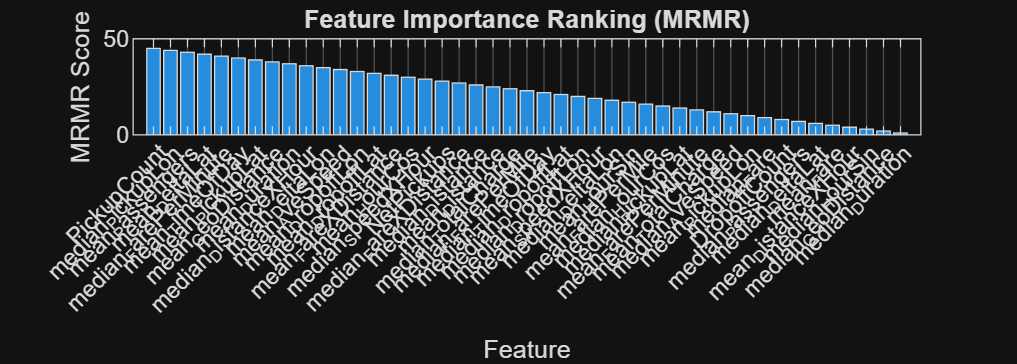

addpath '/MATLAB Drive/Predictive Modeling and Machine Learning/Code Files/Training Functions';

% Filter-based feature selection using fscmrmr
% Remove unwanted predictors first
predictors = removevars(groupedSummaryTable, ...
    {'HourlyBin', 'Region', 'IsHoliday'});

% Separate features and response
X = removevars(predictors, 'Demand');
y = predictors.Demand;

% Run MRMR
idx = fscmrmr(X, y);

% Get feature names
featNames = X.Properties.VariableNames;

% Sort in descending order of importance
[sortedIdx, sortOrder] = sort(idx, 'descend');
sortedNames = featNames(sortOrder);

% Plot
figure('Position', [100, 100, 1400, 500]);
bar(sortedIdx);

xticks(1:length(sortedIdx));
xticklabels(sortedNames);
xtickangle(45);

xlabel('Feature');
ylabel('MRMR Score');
title('Feature Importance Ranking (MRMR)');
grid on;

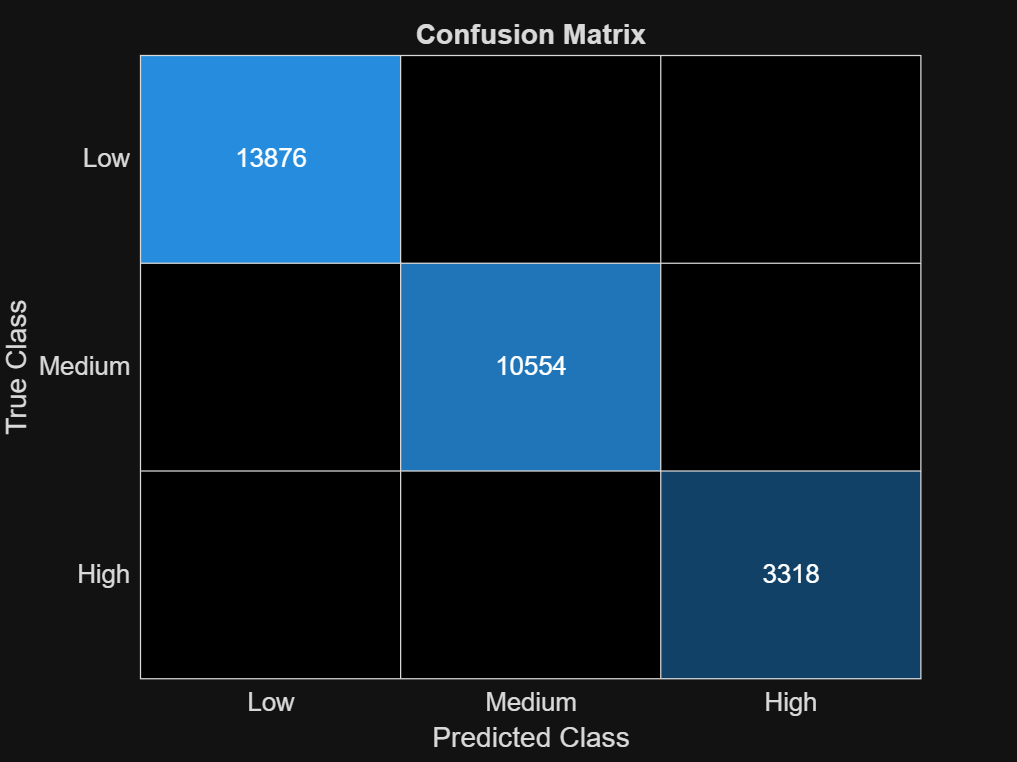

resultsS1 = struct with fields:
             Accuracy: 1
             PerClass: [3×11 table]
       MacroPrecision: 1
          MacroRecall: 1
     MacroSpecificity: 1
              MacroF1: 1
             MacroFPR: 0
             MacroFDR: 0
    WeightedPrecision: 1
       WeightedRecall: 1
           WeightedF1: 1
      ConfusionMatrix: [3×3 double]
           ClassOrder: [3×1 categorical]



rng(42);

cv = cvpartition(height(groupedSummaryTable), 'HoldOut', 0.20);

trainData = groupedSummaryTable(training(cv), :);
testData  = groupedSummaryTable(test(cv), :);

Mdl = trainBaselineClassifier(trainData);

resultsS1 = evaluateModel(Mdl, trainData, "Demand")

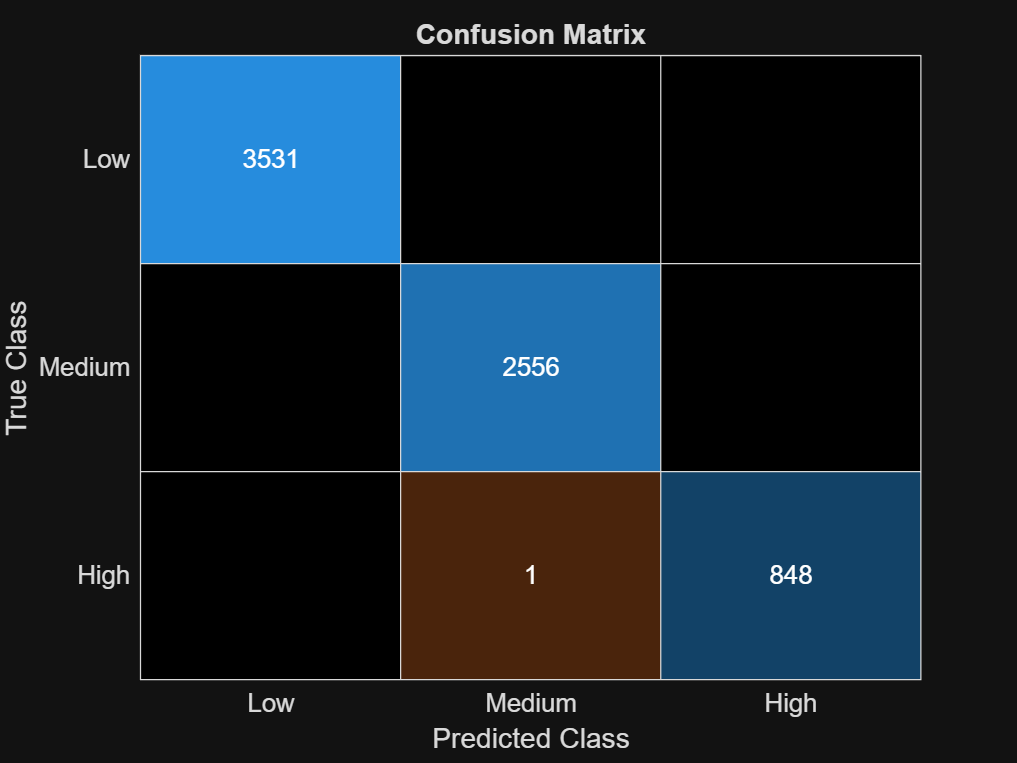

resultsS1Tested = struct with fields:
             Accuracy: 0.9999
             PerClass: [3×11 table]
       MacroPrecision: 0.9999
          MacroRecall: 0.9996
     MacroSpecificity: 0.9999
              MacroF1: 0.9997
             MacroFPR: 7.6104e-05
             MacroFDR: 1.3036e-04
    WeightedPrecision: 0.9999
       WeightedRecall: 0.9999
           WeightedF1: 0.9999
      ConfusionMatrix: [3×3 double]
           ClassOrder: [3×1 categorical]



resultsS1Tested = evaluateModel(Mdl, testData, "Demand")

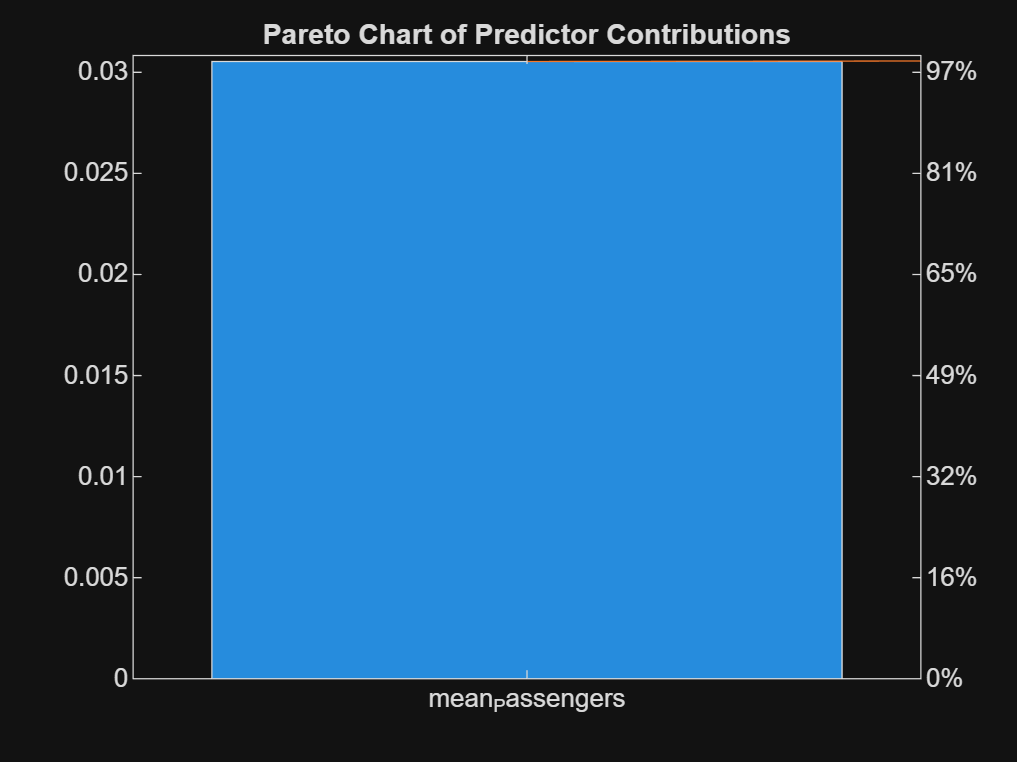


imp = predictorImportance(Mdl.ClassificationEnsemble);

createParetoChartForPredictors(imp, Mdl.ClassificationEnsemble.PredictorNames);


Mdl1_5 = trainPostFeatureEngineeringBaselineClassifier(trainData);

resultsS1_5 = evaluateModel(Mdl1_5, trainData, "Demand")

resultsS1_5Tested = evaluateModel(Mdl1_5, testData, "Demand")

imp1_5 = predictorImportance(Mdl1_5.ClassificationEnsemble);
names = string(Mdl1_5.ClassificationEnsemble.PredictorNames);

[impSorted, idx] = sort(imp1_5, 'descend');
namesSorted = names(idx);

createParetoChartForPredictors(impSorted, namesSorted);